clear all
clc
syms s 

numerador = [5];             
d_0 = [1 0];                    
d_1 = [1, 2];
denominador = conv(d_0, d_1);   
fprintf('*** Función de Transferencia en lazo abierto***\n');

*** Función de Transferencia en lazo abierto***


G_p = tf(numerador, denominador)


G_p =
 
      5
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


G_p_closedloop=feedback(G_p,1)


G_p_closedloop =
 
        5
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.
Model Properties


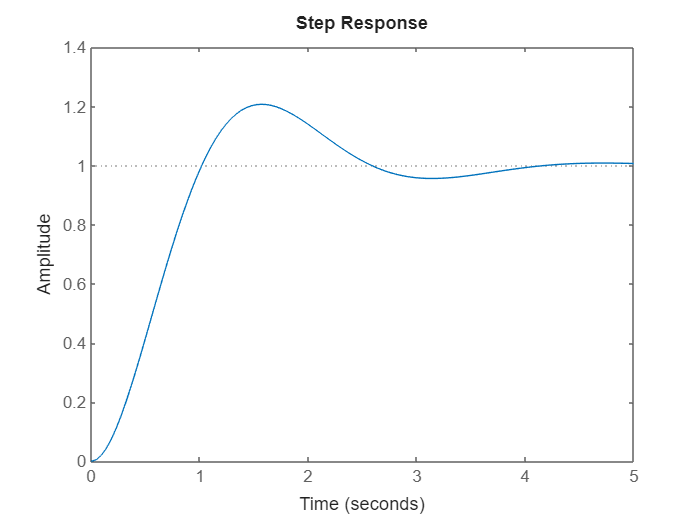

step(G_p_closedloop)
    
hold on

Ts=0.1;
sys_z = c2d(tf(numerador, denominador), Ts, 'zoh')


sys_z =
 
    0.02341 z + 0.0219
  ----------------------
  z^2 - 1.819 z + 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


sys_z_closedloop=feedback(sys_z,1)


sys_z_closedloop =
 
    0.02341 z + 0.0219
  ----------------------
  z^2 - 1.795 z + 0.8406
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


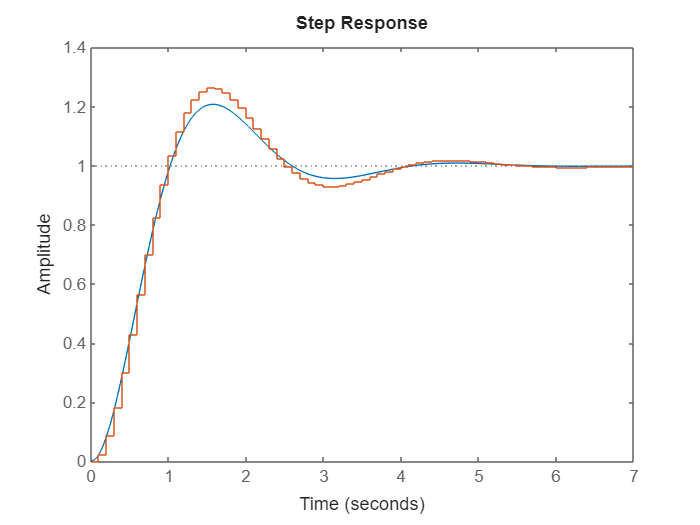

step(sys_z_closedloop)
hold off